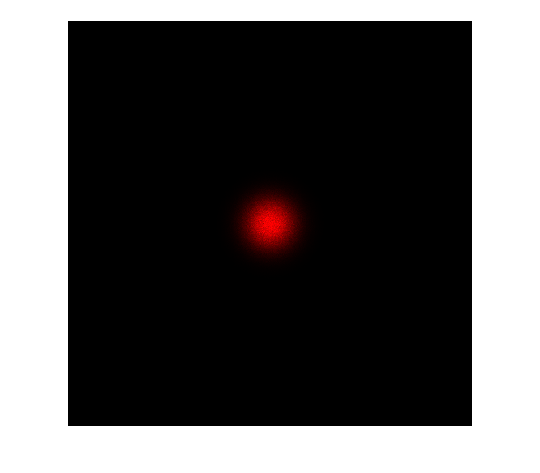

lambda=647e-6;
rate=(1/40);%采样率（global）
beamAmp=1;
beamSize=2;
beamStd=beamSize/2.85;
N=500;
color=wavelength2color(lambda*10^6, 'gammaVal', 2.2, 'maxIntensity', 1, 'colorSpace', 'rgb');
R=linspace(0,color(1),65535)';
G=linspace(0,color(2),65535)';
B=linspace(0,color(3),65535)';
mymap=[R G B];
beam=GaussianBeam(beamAmp,beamStd,lambda);
beams=GaussianBeam.defocused(beam,10,N,rate);
beams=GaussianBeam.beamNoise(beams,0.05,0.05);
imshow(65536*abs(beams).^2,mymap)

# Diffuser

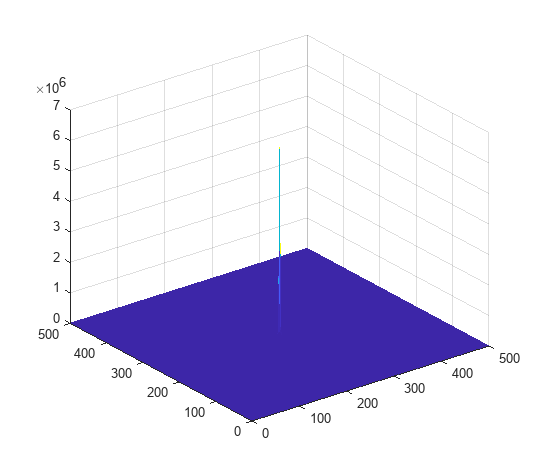

diffuserAngle=0.5;   %散射片散射角度
diffuser=Diffuser(diffuserAngle,lambda);
phase=Diffuser.generateDiffuser(diffuser,rate,[N,N]);

beamss=beams.*phase;
corr=autoCorr2D(beamss);
mesh(abs(corr).^2)